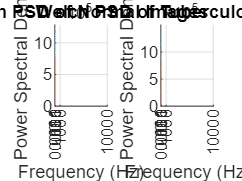

rng(45);  % Set random seed for reproducibility
classNormal = "Normal";
classTB = "Tuberculosis";
dataFolder = "C:\Users\Avrajit\Downloads\TB_Chest_Radiography_Database";
LungImds = imageDatastore(dataFolder, "IncludeSubfolders", true, "LabelSource", "foldernames");

% Find indices for both classes
idxClassNormal = find(LungImds.Labels == classNormal);
idxClassTB = find(LungImds.Labels == classTB);

% Randomly select 100 images from each class
sampleSize = 100;
selectedNormalIndices = randsample(idxClassNormal, sampleSize);
selectedTBIndices = randsample(idxClassTB, sampleSize);

% Combine selected indices
selectedIndices = [selectedNormalIndices; selectedTBIndices];

% Initialize results table
results = table('Size', [0, 5], 'VariableTypes', {'string', 'double', 'double', 'double', 'double'}, ...
                'VariableNames', {'Class', 'PeakPSD', 'RMS', 'SNR', 'Frequency'});

% Define parameters for Welch's method
window = hamming(256);  % Hamming window of length 256
noverlap = 128;         % 50% overlap
nfft = 512;             % Number of FFT points

% Prepare figure for PSD plot
figure;

for i = 1:length(selectedIndices)
    % Read the image
    img = readimage(LungImds, selectedIndices(i));

    % Convert images to grayscale if they are RGB
    if size(img, 3) == 3
        img = rgb2gray(img);
    end

    % Flatten the image to a 1D array for PSD calculation
    img1D = double(img(:));

    % Compute the PSD using Welch's method
    [psd_welch, f] = pwelch(img1D, window, noverlap, nfft, 'psd');

    % Calculate the peak PSD
    peakPSD = max(psd_welch);
    
    % Calculate RMS
    RMS = sqrt(mean(psd_welch));
    
    % Assuming noise is the mean of the PSD for simplicity
    noise = mean(psd_welch);
    if noise > 0
        SNR = 10 * log10(peakPSD / noise); % SNR in dB
    else
        SNR = NaN; % If noise is zero, SNR is undefined
    end

    % Get the class label from the datastore
    classLabel = string(LungImds.Labels(selectedIndices(i)));
    
    % Append results to the table
    results = [results; {classLabel, peakPSD, RMS, SNR, f}]; 
    
    % Plot PSD
    subplot(1, 2, find(unique(results.Class) == classLabel));
    hold on;
    semilogx(f, psd_welch);
end

% Set frequency limits and labels for Normal images
subplot(1, 2, 1);
title('Welch PSD of Normal Images');
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density');
xlim([10^-4, 10^4]); % Set frequency range from 10^-4 to 10^4
xticks([10^-4, 10^-3, 10^-2, 10^-1, 10^0, 10^1, 10^2, 10^3, 10^4]); % Set ticks
grid on; % Turn on grid

% Set frequency limits and labels for Tuberculosis images
subplot(1, 2, 2);
title('Welch PSD of Tuberculosis Images');
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density');
xlim([10^-4, 10^4]); % Set frequency range from 10^-4 to 10^4
xticks([10^-4, 10^-3, 10^-2, 10^-1, 10^0, 10^1, 10^2, 10^3, 10^4]); % Set ticks
grid on; % Turn on grid


% Write the results to a CSV file
writetable(results, 'psd_analysis_100_samples.csv');

disp('PSD analysis for 100 samples completed and results saved to psd_analysis_100_samples.csv');

PSD analysis for 100 samples completed and results saved to psd_analysis_100_samples.csv


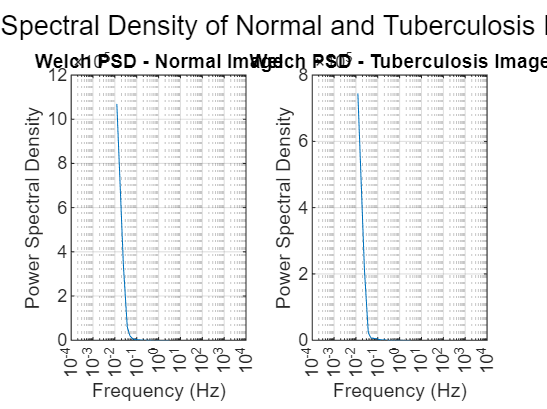

Welch PSD plots for Normal and Tuberculosis images completed.


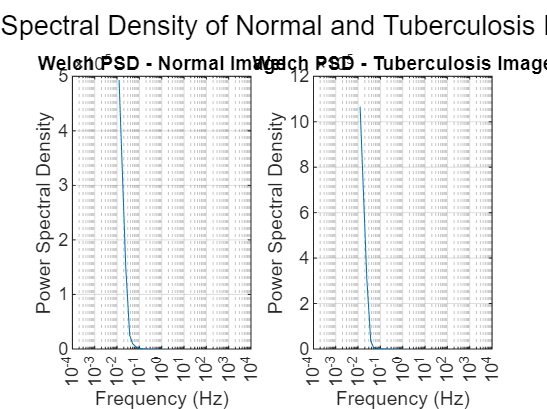

Welch PSD plots for Normal and Tuberculosis images completed.


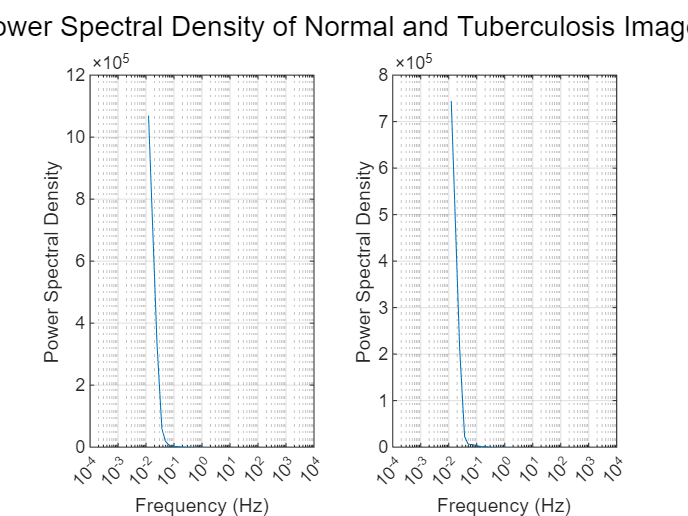

Welch PSD plots for Normal and Tuberculosis images completed.


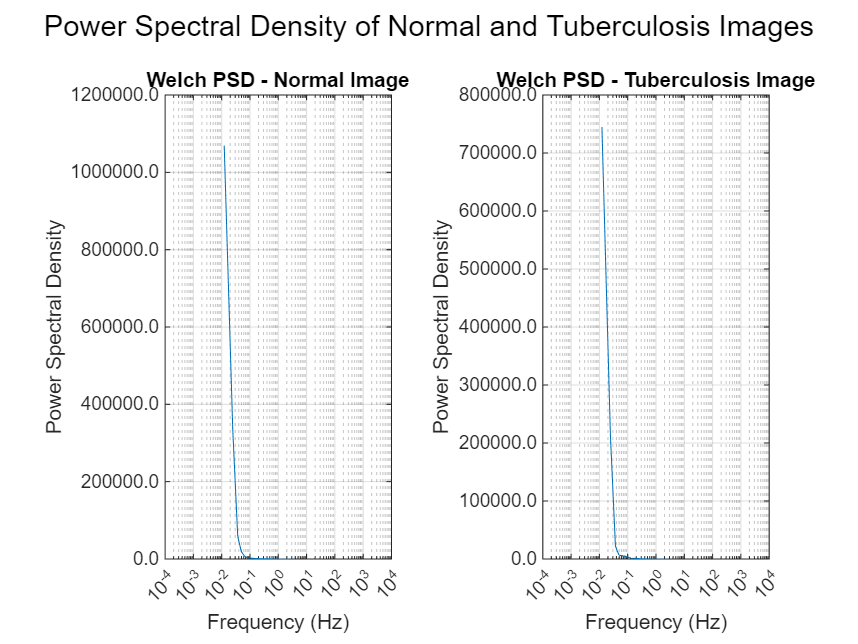

Welch PSD plots for Normal and Tuberculosis images completed.


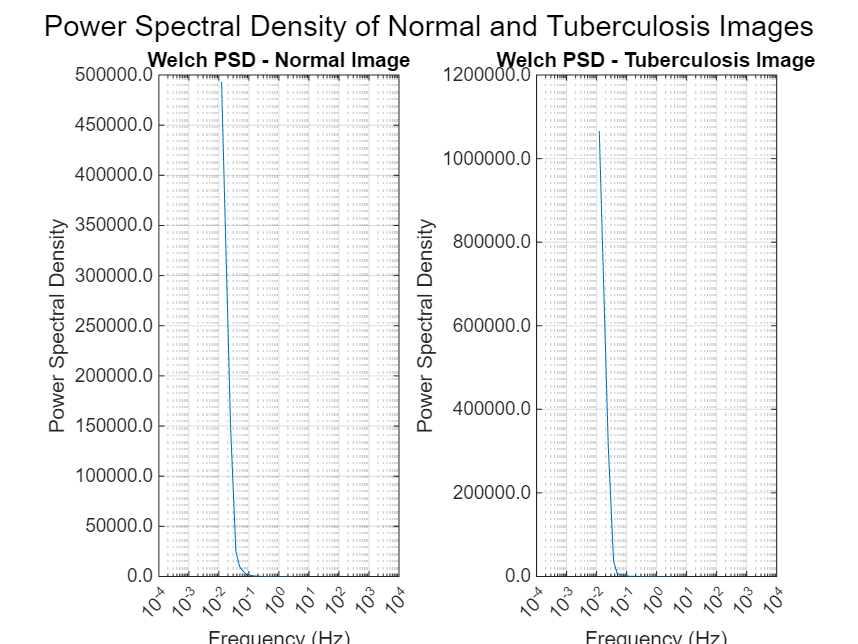

Welch PSD plots for Normal and Tuberculosis images completed.
